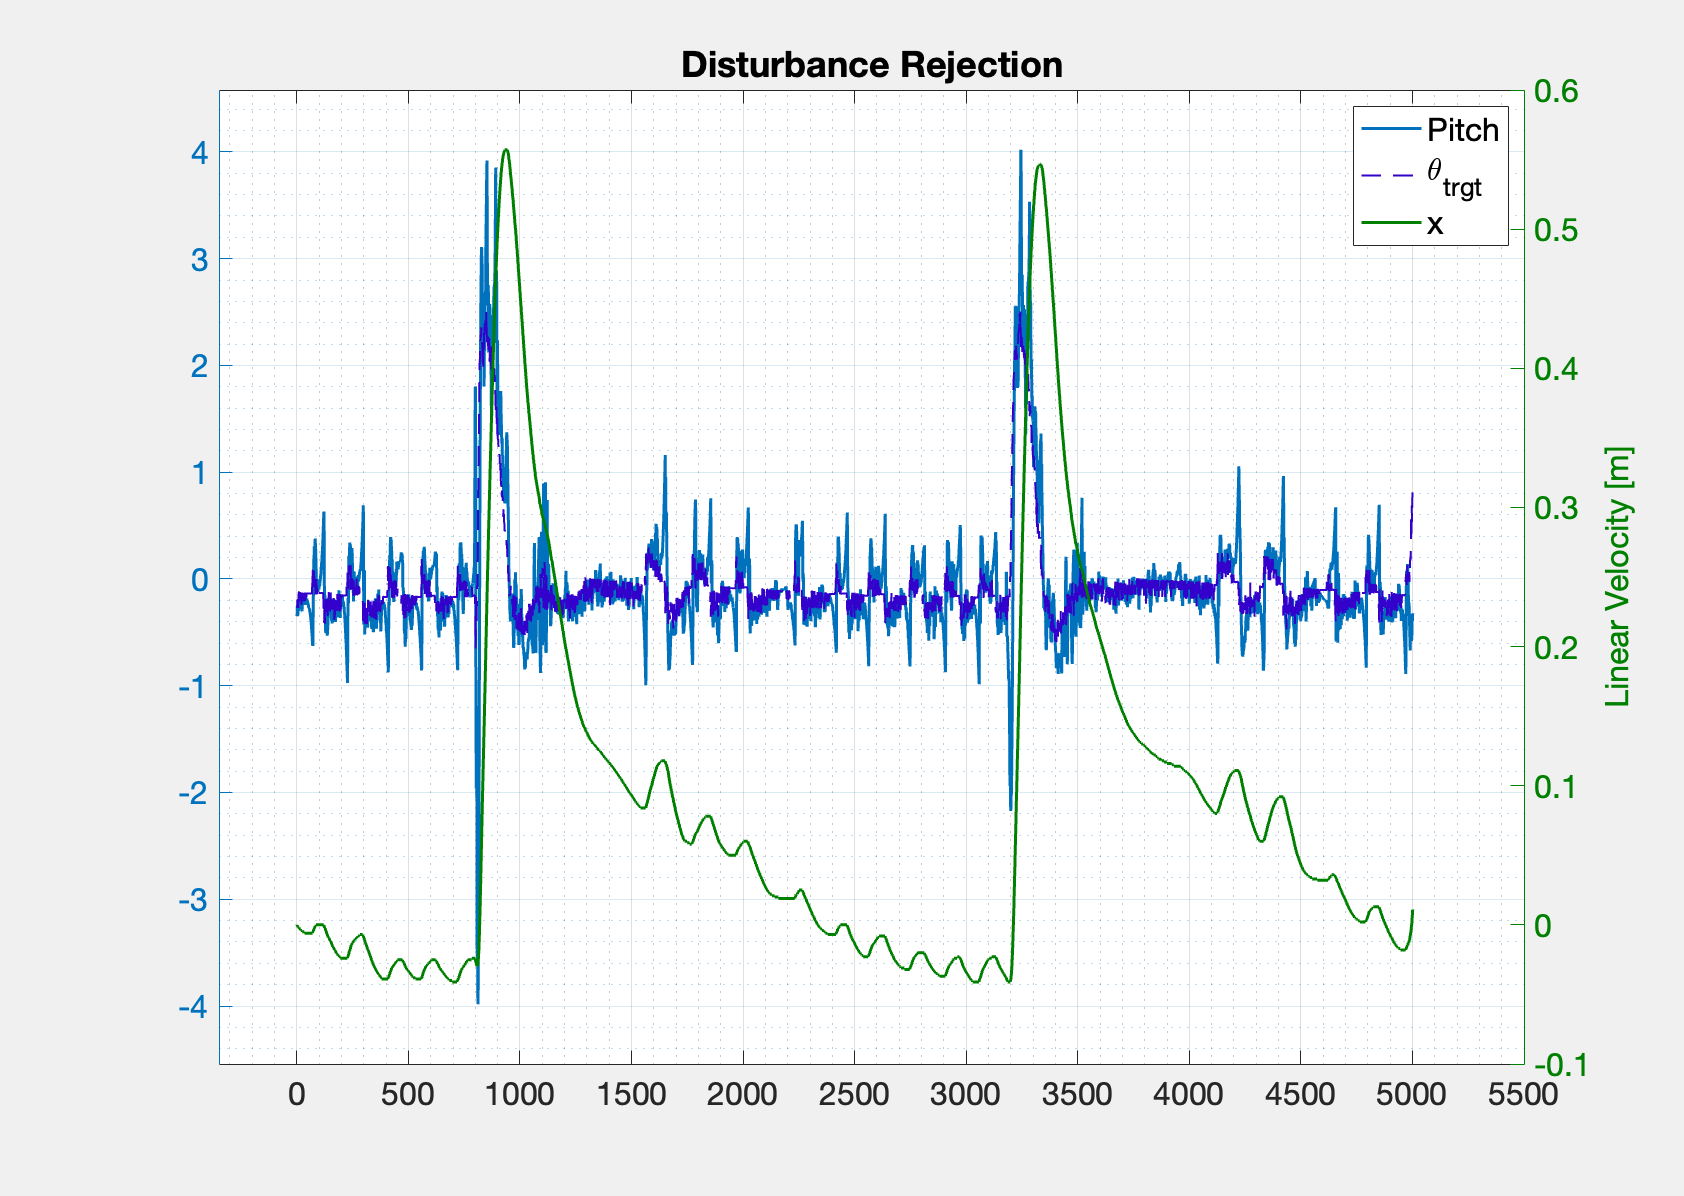

clear; clc; close all;
addpath("utils/")
dataPath = 'DataSets/BalancingTests/disturbance.csv';
[~, timedelta, data] = parseDataSet(dataPath);

start = 3000;
stop =8000;

pitch = data(start:stop,1);
linvel = data(start:stop,15);
pitch_trgt = data(start:stop,17);
xg = data(start:stop,22);
fig = figure;
yyaxis left
ylabel('Pitch [deg]');
plot(pitch, 'LineWidth',1.5); hold on;
plot(pitch_trgt, 'LineWidth',1, 'Color',[0.2, 0, 0.8]);

yyaxis right
ylabel("Linear Velocity [m]");
plot(xg - xg(1), 'LineWidth',1.5, 'Color', [0 0.5 0]); hold off;
ax = gca;
ax.YColor = [0 0.5 0]; 
grid on; grid minor; 
legend('Pitch', '\theta_{trgt}', 'x')

axis padded
fontsize(16, 'points');
plottitle = "Disturbance Rejection";
title(plottitle, 'FontSize', 18)
folderpath = fullfile("..", "Docs", "Y3Report", "Images", "Graphs", filesep);
filepath = fullfile(folderpath, plottitle + ".pdf");
set(fig, 'Units', 'inches', 'Position', [0 0 11.7 8.3]);

exportgraphics(fig, filepath);
set(gcf,'Visible', 'on');